[y1,Fs] = audioread("arctic_a0001.wav");%read the waveform
sp = y1(:,1);%where first column has speech information
egg = y1(:,2);%where second column has egg information
m = resample(sp,8000,Fs);
audiowrite('MaleVoice.wav',m,8000);

**Sampled wave Characteristics**

[y2,F2] = audioread("MaleVoice.wav");

info = audioinfo("MaleVoice.wav")

info = struct with fields:
             Filename: '/MATLAB Drive/MaleVoice.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 8000
         TotalSamples: 28240
             Duration: 3.5300
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


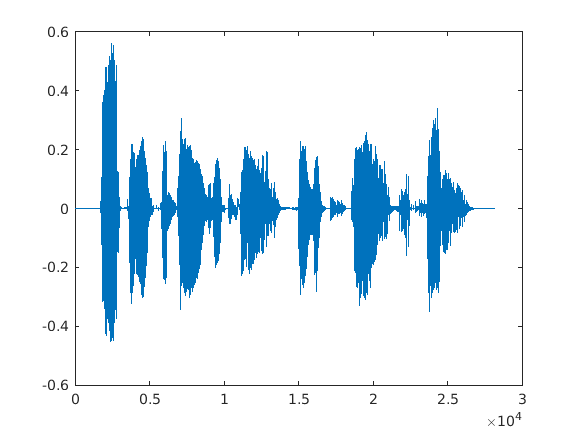

sp = y1(:,1);%where first column has speech information
egg = y1(:,2);%where second column has egg information
t = 0:1/Fs:(length(m)-1)/Fs;
plot(m)%plot the waveform

Auto correlation

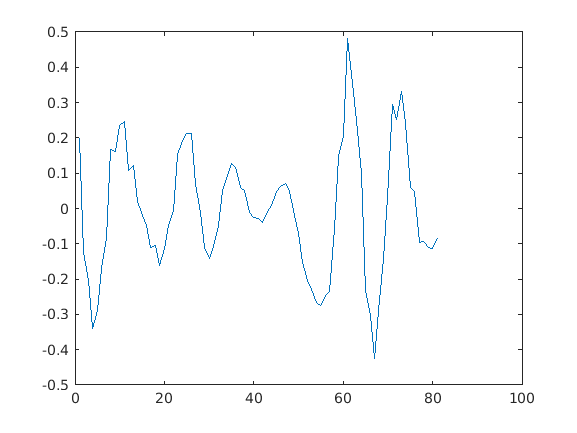

s = m(2000:2080);
plot(s)

Auto correlation function

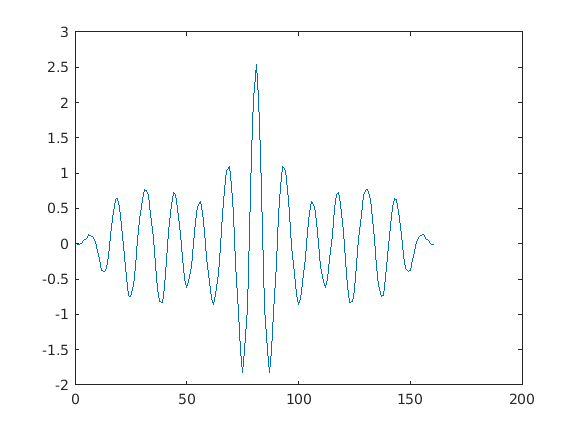

figure
r = xcorr(s);
plot(r)

A 20 ms section of speech signal

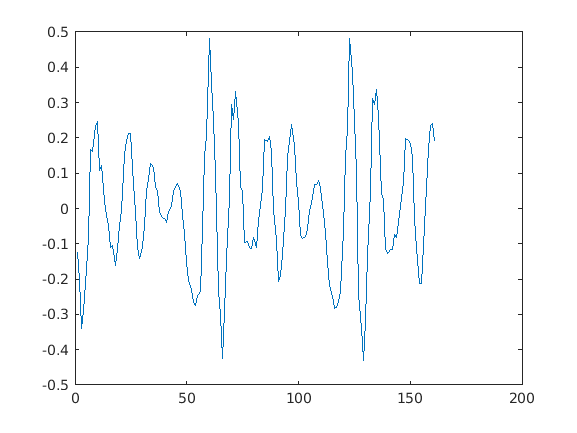

s = m(2001:2161);
plot(s)

Autocorrelation function

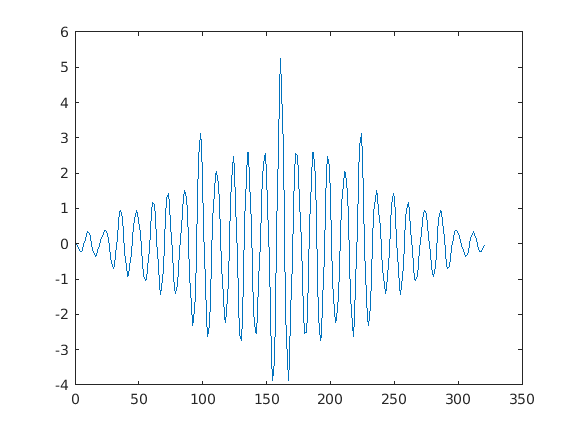


figure
r = xcorr(s);
plot(r)

A 40ms section of speech signal

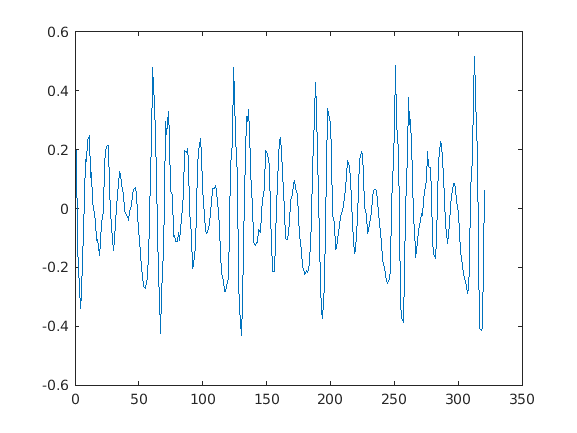

s = m(2000:2320);
plot(s)

Autocorrelation function

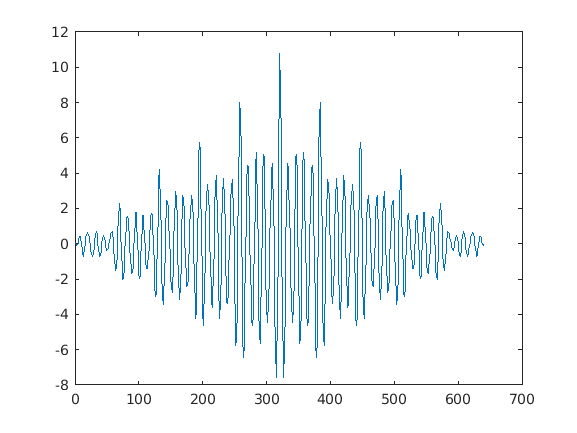

figure
r = xcorr(s);
plot(r)

Unvoiced Signal with 10ms section of unvoiced signal

s = m(14400:1600);
plot(s)

Autocorrelation function

figure
r = xcorr(s);
plot(r)